load("data.mat")

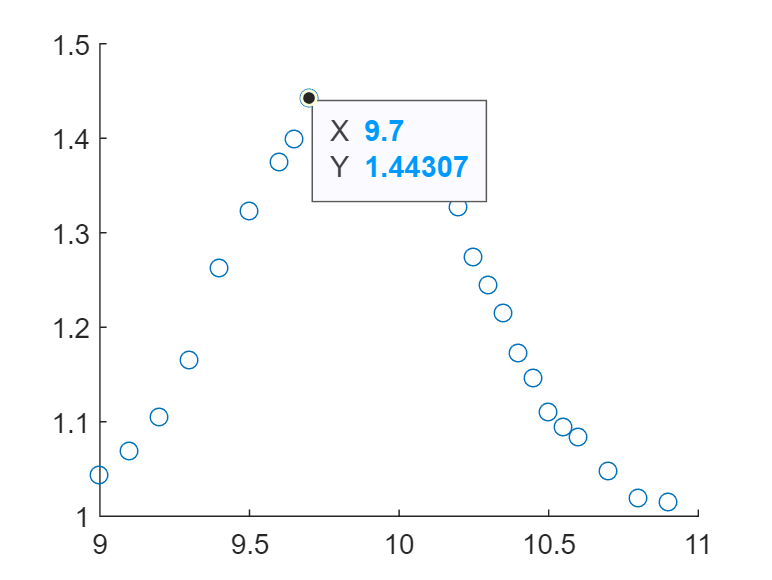

scatter(x1,g21)

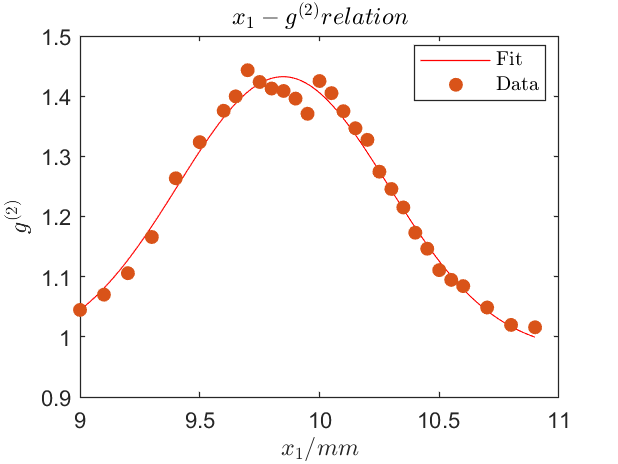

% 定义自定义拟合函数
ft = fittype('a*exp(-((x-b)/(2*c))^2)+d', 'independent', 'x', 'coefficients', {'a', 'b', 'c', 'd'});

% 进行拟合
[fitresult, gof] = fit(x1(:), g21(:), ft, 'StartPoint',[0.47,9.8,0.3,1]);

% 提取拟合参数
coeffs = coeffvalues(fitresult);

% 绘制散点图和拟合曲线
figure;
plot(fitresult);
hold on;
scatter(x1, g21, 'filled');
hold off;

% 添加图例，使用 LaTeX 格式
legend({'$\mathrm{Fit}$', '$\mathrm{Data}$'}, 'Interpreter', 'latex', 'Location', 'Best');
title('$x_1-g^{(2)}relation$','Interpreter','latex');
xlabel('$x_1/mm$', 'Interpreter', 'latex');
ylabel('$g^{(2)}$', 'Interpreter', 'latex');


% 显示拟合参数和拟合优度
fprintf('拟合参数：a = %f, b = %f, c = %f, d = %f\n', coeffs(1), coeffs(2), coeffs(3), coeffs(4));

拟合参数：a = 0.458973, b = 9.847962, c = 0.310466, d = 0.973404


fprintf('拟合优度：R-square = %f\n', gof.rsquare);

拟合优度：R-square = 0.984643


coeffs(1)

ans = 0.4590

coeffs(2)

ans = 9.8480

1./(2.*coeffs(3)).^2

ans = 2.5937

coeffs(4)

ans = 0.9734

coeffs(1)+coeffs(4)

ans = 1.4324

var(g21)

ans = 0.0215

a=0.839; b=1.433; c=0.824;
b+0.5*(a+c)

ans = 2.2645

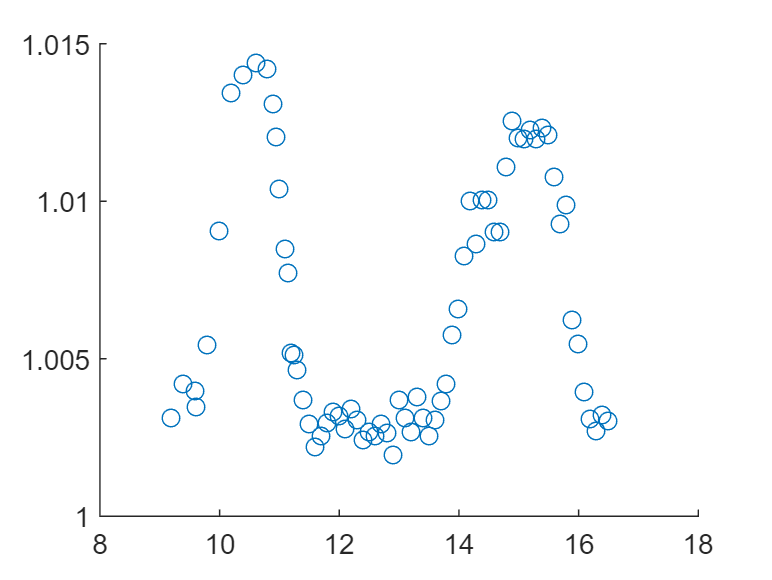

scatter(x2,g22)

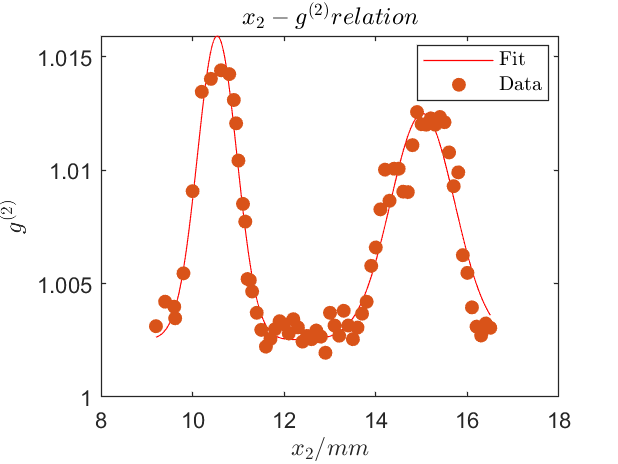

% 定义自定义拟合函数
ft = fittype('a1*exp(-((x-b1)/(2*c1))^2)+a2*exp(-((x-b2)/(2*c2))^2)+d', 'independent', 'x', 'coefficients', {'a1', 'b1', 'c1','a2','b2','c2', 'd'});

% 进行拟合
[fitresult, gof] = fit(x2(:), g22(:), ft, 'StartPoint',[0.012,10.52,0.4,0.011,14.9,0.67,1.003]);

% 提取拟合参数
coeffs = coeffvalues(fitresult);

% 绘制散点图和拟合曲线
figure;
plot(fitresult);
hold on;
scatter(x2, g22, 'filled');
hold off;

% 添加图例，使用 LaTeX 格式
legend({'$\mathrm{Fit}$', '$\mathrm{Data}$'}, 'Interpreter', 'latex', 'Location', 'Best');
title('$x_2-g^{(2)}relation$','Interpreter','latex');
xlabel('$x_2/mm$', 'Interpreter', 'latex');
ylabel('$g^{(2)}$', 'Interpreter', 'latex');


% 显示拟合参数和拟合优度
coeffs

coeffs =     0.0134   10.5364    0.3051    0.0100   15.0211    0.4966    1.0025


fprintf('拟合优度：R-square = %f\n', gof.rsquare);

拟合优度：R-square = 0.941774


g23=g22-1;

coeffs(2)-coeffs(5)

ans = -4.4847

cftool